#  Basic Orbital Mechanics

We want to investigate what happens when we put a satellite in orbit around the earth and, more specifically, how we can transition the satellite to a geostationary orbit. We will explore a highly idealized model that will nontheless demonstrate the basic behavior. Our main simplifying assumptions are:

- The Earth and the satellite are the only two objects in the universe (there are no other gravitational effects).

- All orbits are planar (two-dimensional) in the Earth's equatorial plane.

- Both the earth and the satellite are conceived of as points at their respective centers.

Newton's Law of Universal Gravitation states that two particles attract each other with a force whose magnitude is directly proportional to the product of their masses and inversely proportional to the square of the distance between their centers. That is  


$$|F| = \frac{G m_1 m_2}{r^2}$$


where $G$ is a universal constant known as the constant of gravitation.

We put the Earth at the origin of our coordinate system and let the satellite orbit around it. We will use a notational trick to simplify our approach to dynamics problems in the plane by working in the complex plane. Specifically, we let the position of the satellite at time $t$ be given by a complex valued function $z(t)$, and will assume that the satellite has mass $m_1$and that the Earth has mass $m_2$. The magnitude of the force acting on the satellite is then


$$|F| = \frac{G m_1 m_2}{|z(t)|^2}$$


Since we have put the Earth at the origin, the force on the satellite acts in a direction opposite to its position.  Normalizing and negate the position vector, we get a unit vector pointing in the direction in which the force is acting:


$$-\frac{z(t)}{|z(t)|}$$


Multiplying this by the magnitude gives us the force vector acting on the satellite as


$$F = -\frac{z(t)}{|z(t)|^3} G m_1 m_2$$


Newton's Second Law of Motion states the force acting on a body is equal to the product of the mass of the body and its acceleration.  Thus,


$$F = m_1 \ddot{z}(t)$$


which leads us to the following nonlinear ODE for the position of the satellite at time $t$:

$\ddot{z}(t) = -\frac{z(t)}{|z(t)|^3}\mu$,

where $\mu = Gm_2$ is a constant.  In SI units, $\mu = 3.986005\times10^{14}\frac{m^3}{s^2}$.  Note that the mass $m_1$ of the satellite does not appear in the ODE.

As usual, we represent this ODE using a chebop:

mu = 3.986005e14;
N = chebop(@(t, z) diff(z, 2) + mu*z./abs(z).^3);

## Example:  The Orbit of the Moon

The moon is by far the most famous of Earth's satellites.  Let us simulate its orbit computationally by solving the ODE. 

First, we need a time scale over which to simulate.  We'll aim for one complete orbit, which we know takes a month to complete.  There are several definitions for "a month", but for our purposes, the correct one is a "sidereal month", which is a bit more than 27 days and can be written in seconds as:

lunarmonth = 27.3217*86400;

Now, all we need to do is assign this timescale as the domain of our chebop and give it the right initial conditions (which will be explained later):

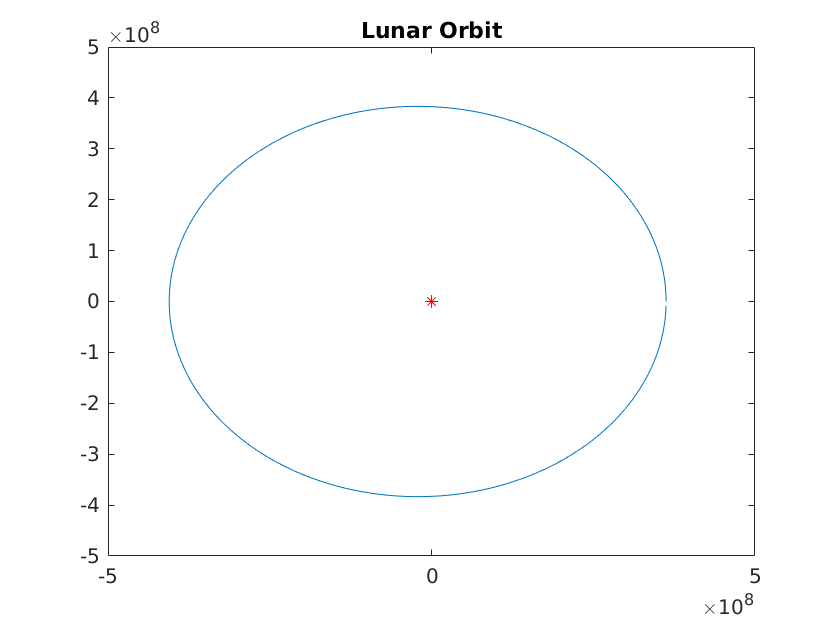

N.domain = [0 lunarmonth];

d0 = 362600000;
v0 = 1077.284*1i;
N.lbc = [d0; v0];

z = N\0;

arrowplot(z);
axis([-5 5 -5 5]*1e8)
hold on;
plot(0, 0, 'r*');
hold off;
title('Lunar Orbit');

Observe that all of our numbers line up:  the simulated moon makes one complete orbit of the Earth in one simulated sidereal month's worth of time.

There are two very important geometrical parameters that we need to know about an orbit around the Earth. The radius of the *perigee*, denoted by$r_p$, is the smallest distance between the orbiting satellite and the center of the earth at any point in the orbit, and the radius of the *apogee*, denoted by $r_a$ is the greatest distance.  We can create a  function that tells us our distance from the center of the earth at time $t$ by

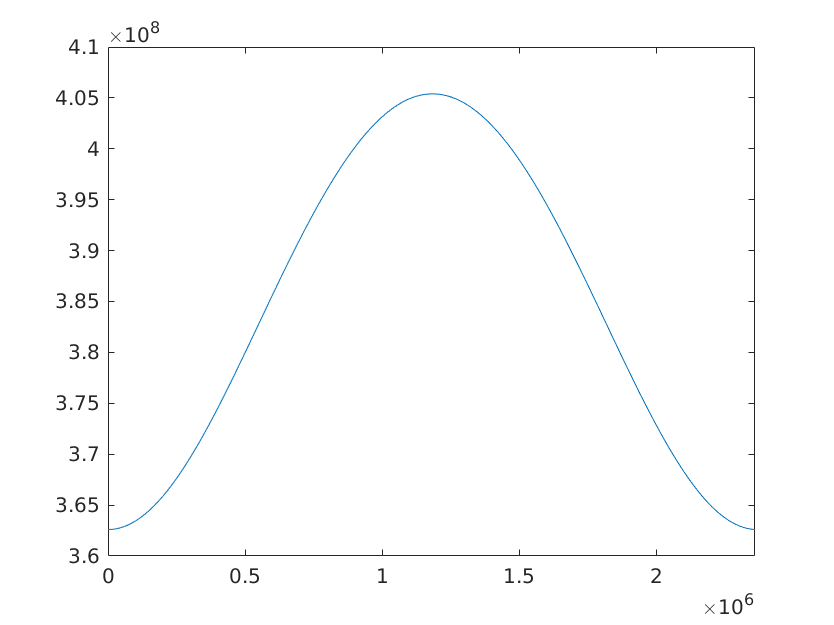

dist = abs(z);
plot(dist);

The radii of perigee and apogee can then be found by finding the minimum and maximum respectively 

r_p = min(abs(z))

r_p =    362600000

r_a = max(abs(z))

r_a =      4.053957689818914e+08

(These values are in units of meters.)

An important figure of merit for an elliptical orbit is its *eccentricity*, which is defined to be $e = \frac{r_a-r_p}{r_a+r_p}$.  For our idealized moon it works out to be

ecc = (r_a - r_p)/(r_a + r_p)

ecc =    0.055723964519524

The eccentricity describes the deviation of an orbit from circularity.  If the perigee and the apogee are the same, the eccentricity is zero, and the orbit is circular.  Larger eccentricities correspond to orbits that are more "skewed".

The value of $r_p$ here should look familiar:  it happens to be the distance we input above for the initial position of the moon.  The radii of perigee and apogee are very important parameters for characterizing orbits, and you can find them for many celestial bodies of interest in astronomical tables.  Looking in such a table, we find that $r_a$ for the moon is approximately $4.05400 \times 10^8$ meters, which is in good agreement with the computation above.

## A Circular Geostationary Orbit

For an orbit to be geostationary we need three things. 

- The orbital period must be one day.  Specifically, it must be one *stellar* day, which is roughly 86,164 seconds.  (This is about 4 minutes shorter than a solar day.)

- The distance between the Earth and the satellite should remain fixed (i.e., the orbit should have zero eccentricity).

- The satellite must be orbiting in the same direction as the earth is rotating.

It can be shown that the distance between the center of the earth and a satellite in geostationary orbit is 42,164 kilometers. We can get our model to show this orbit by changing the initial conditions.  (We will also change the domain to just a couple of stellar days so we can see two complete orbits.)

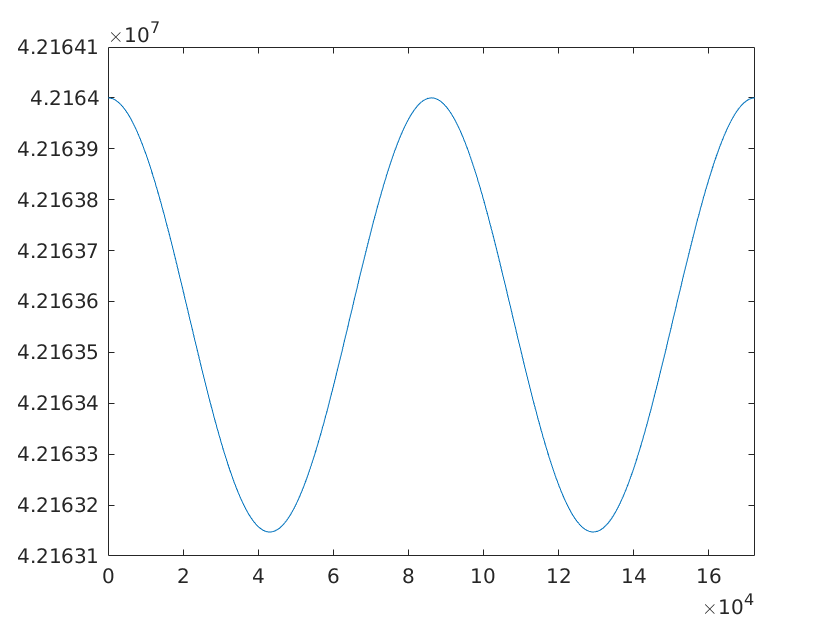

stellar = 86164;
N.domain = [0 2*stellar];

r = 42164000;
v0 = 2*pi*r/stellar*1i;
N.domain = [0 2*stellar];
N.lbc = [r; v0];

z_gs = N\0;
dist = abs(z_gs);
plot(dist);

It clearly isn't perfectly circular---a consequence of limited precision---but if we compute the eccentricity, we see that it is very close to zero:

r_p = min(abs(z_gs))

r_p =      4.216314710078790e+07

r_a = max(abs(z_gs))

r_a =      4.216400000000001e+07

ecc = (r_a - r_p)/(r_a + r_p)

ecc =      1.011417131300703e-05

## A Hohmann Transfer Orbit

Satellites destined for geostationary orbit are not taken there directly.  Instead, they are first put into a *transfer orbit*, and then the satellite is moved from the transfer orbit into geostationary orbit by firing its thrusters.  One type of transfer orbit is the *Hohmann transfer orbit*

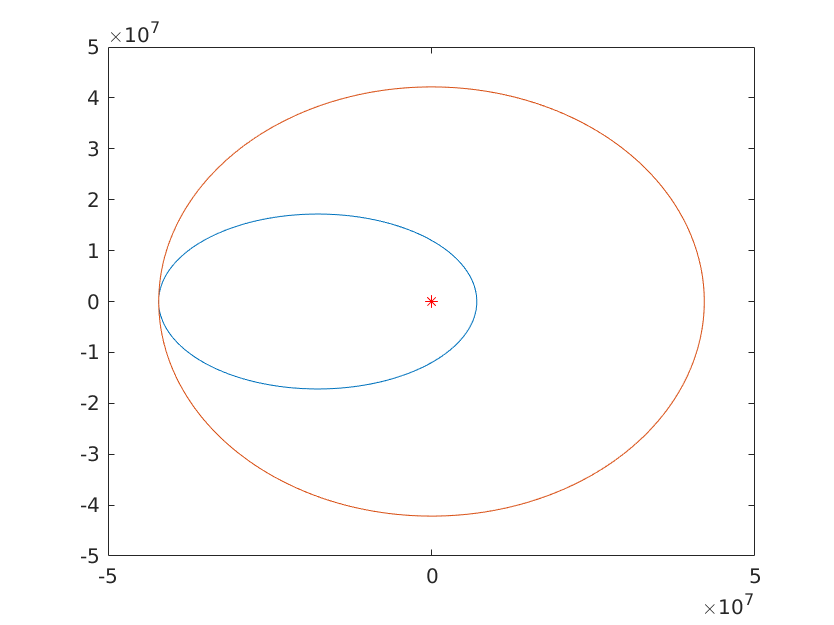

N.domain = [0 40000];

v0 = 9883*1i;
d0 = 7000000;
N.lbc = [d0; v0];

z = N\0;

plot(z);
axis([-5 5 -5 5]*1e7);
hold on;
plot(0, 0, 'r*');
plot(z_gs);
hold off;

The radius of the Hohmann transfer orbit at apogee is equal to the radius of the geostationary orbit:

max(abs(z))

ans =      4.217300344872294e+07

Once the satellite reaches apogee in the Hohmann orbit, it fires its thrusters to change its velocity to match that needed for the geostationary orbit.  We can't simulate an instantaneous burn like this (limitation of our software), but we can approximate it using a burn over a very short time interval:

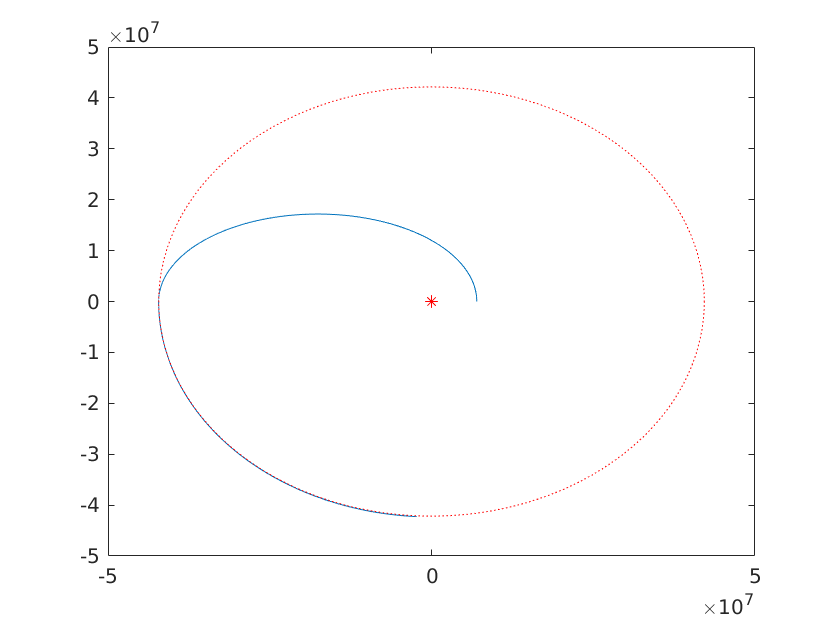

[M, TM] = max(abs(z));
t = chebfun(@(t) t, N.domain);
burn = -1.2*1i*(t < (TM + 600)).*(t > (TM - 600));

z = N\burn;

plot(z);
axis([-5 5 -5 5]*1e7);
hold on;
plot(0, 0, 'r*');
plot(z_gs,'r:'); 
hold off;

The problem is that this requires a lot of thrust.  Your job in this project is to explore making the transition with a low thrust propulsion system.

## Low Thrust Transition to a Geostationary Orbit 

One can transition to a geostationary orbit using low thrust by starting from a *supersynchronous transfer orbit, *which has a radius at apogee greater than that of the geostationary orbit.  Here is one such orbit:

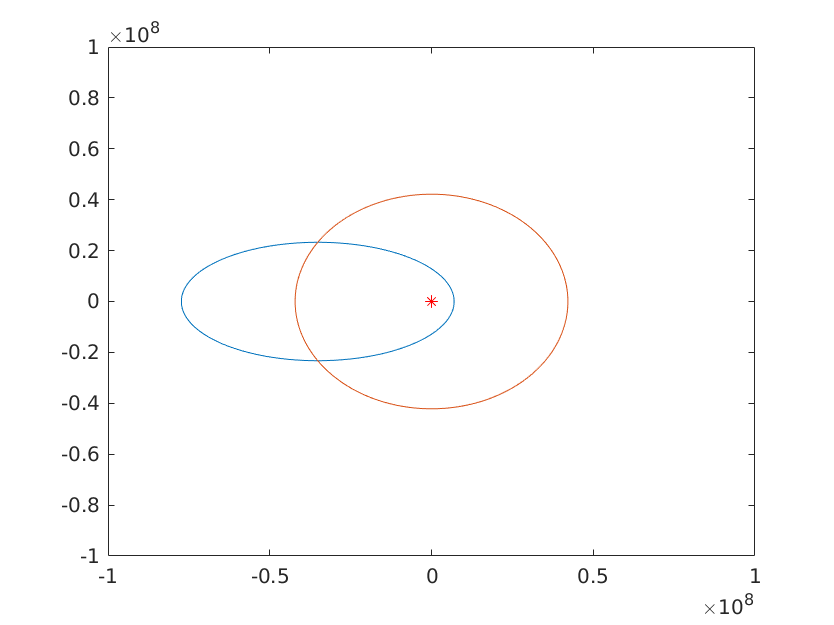

tspan = [0 10*stellar];
N.domain = tspan;

d0 = 7000000;
v0 = 10219.21*1i;
N.lbc = [d0; v0];

z = N\0;

plot(z);
axis([-5 5 -5 5]*2e7);
hold on;
plot(0, 0, 'r*');
plot(z_gs);
hold off;

Your task in this project is to find a burn that will move the satellite from this orbit to the geostationary one.  There are many ways to accomplish this.  To simplify things, you will use a burn that is a fixed, continuous thrust of fixed duration and fixed direction.  You will be given the thrust.  The duration and direction are yours to determine.

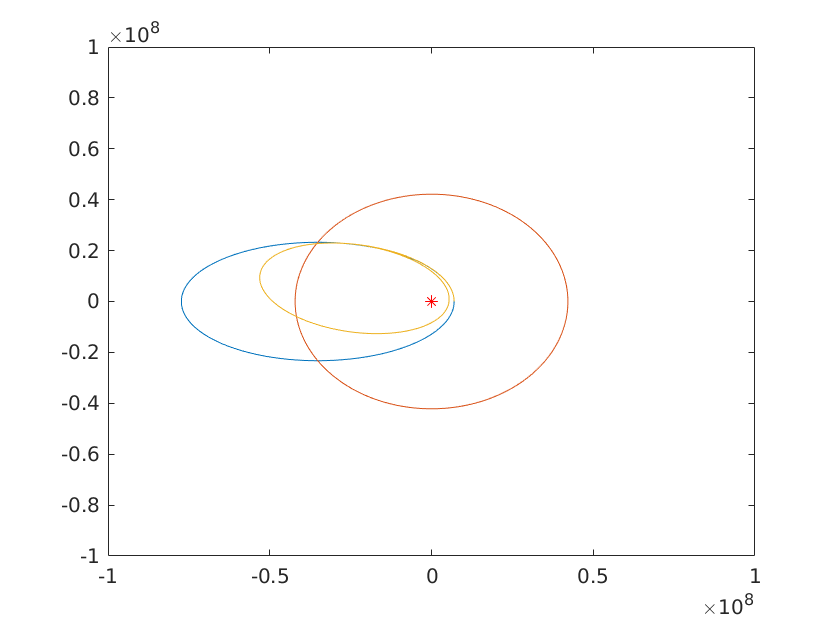

t = chebfun(@(t) t,tspan);
burn = @(duration, direction, thrust) direction/abs(direction)*thrust*(t <= duration);

zz = N\burn(10000, 1, .05);

plot(z);
axis([-5 5 -5 5]*2e7);
hold on;
plot(0, 0, 'r*');
plot(z_gs);
plot(zz);
hold off